# Laboratorio 2 - Modelo geométrico inverso

**Grupo 8**

Ardila, Juan Andrés

López, Nicolás

Rojas, Juan Camilo

Nuestro robot: Fanuc R-2000iC/125L

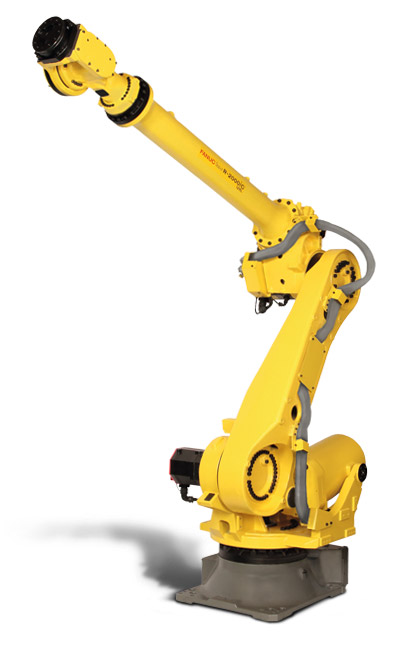

- Determine el modelo geométrico inverso del robot asignado haciendo uso de la metodología explicada en clase. Haga una descripción detallada del proceso haciendo uso de imágenes y dibujos que ayuden visualizar de dónde provienen las ecuaciones encontradas.

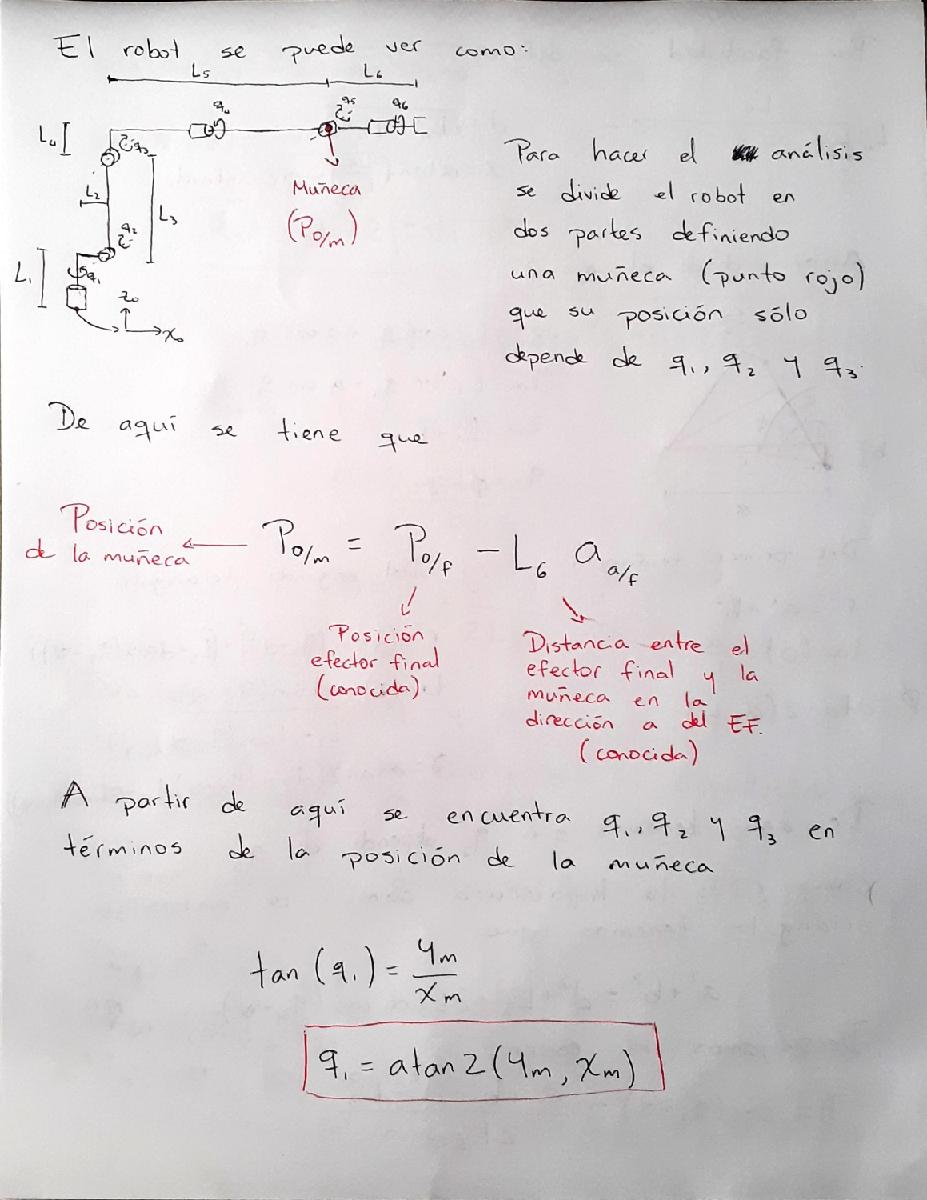

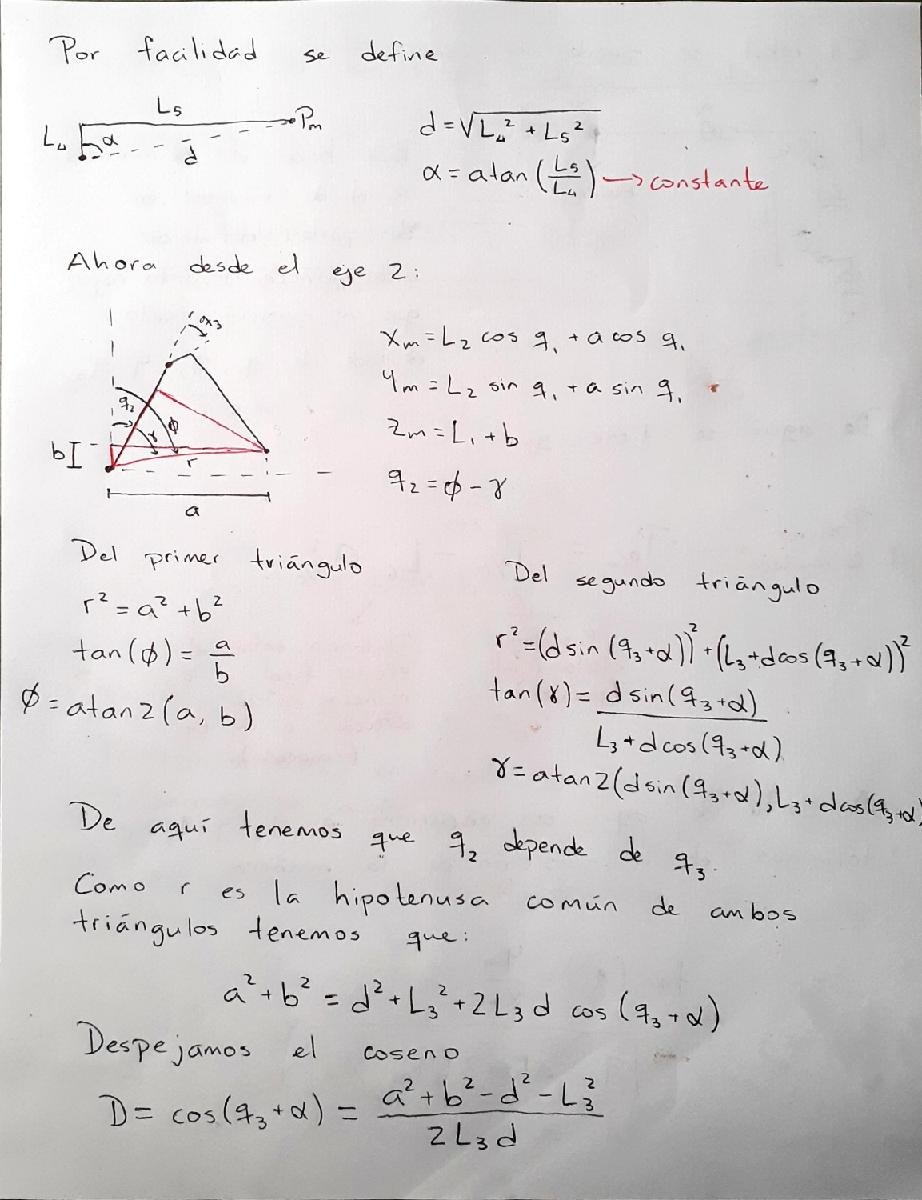

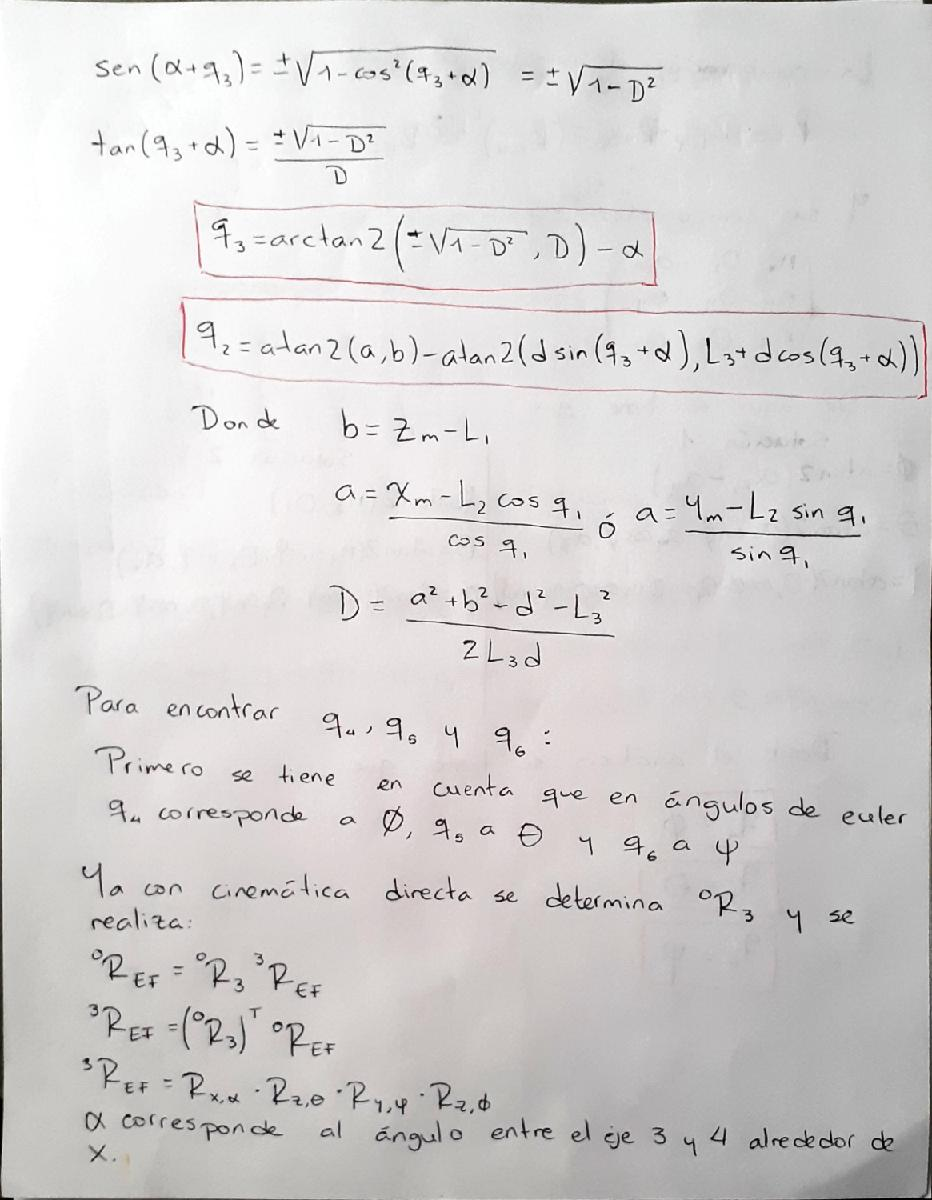

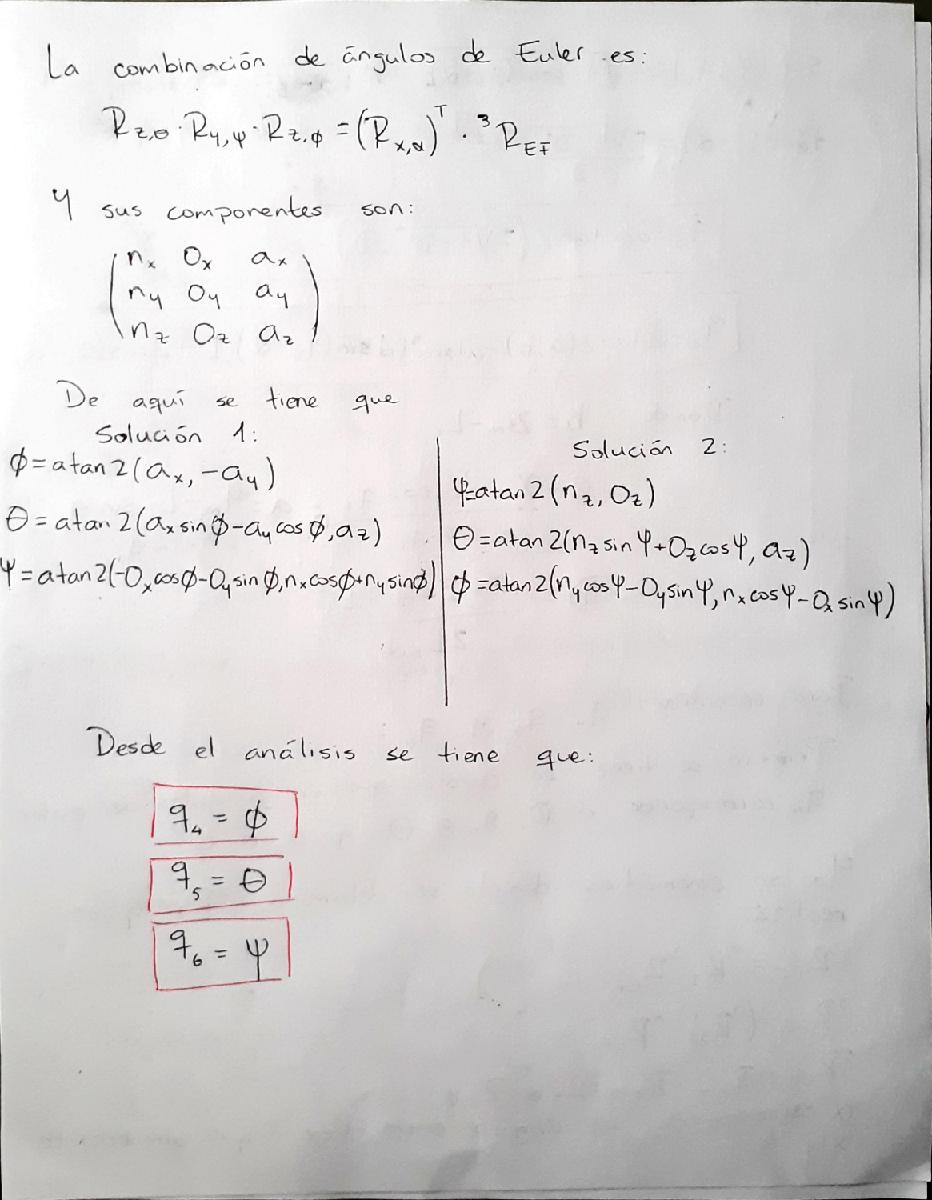

2. En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones.

Existen al final del análisis dos soluciones para los ángulos de la muñeca, por lo que se puede tener codo arriba y codo abajo. A su vez, si vemos la solución anterior a la muñeca podemos ver que la variable «a» tiene dos soluciones, por lo que puede ser hombro izquierda y hombro derecha. De esta manera tenemos en total 4 soluciones: codo arriba hombro derecha, codo arriba hombro izquierda, codo abajo hombro derecha y codo abajo hombro izquierda.

A continuación veremos el robot como se describió en el laboratorio pasado:

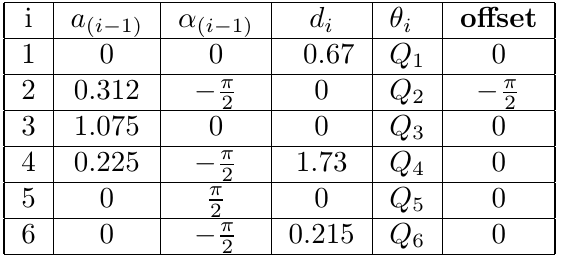

clear
L(1) = Link('revolute','alpha',0,    'a', 0,    'd',0.67, 'offset',0,  ...
    'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha',-pi/2,'a', 0.312,'d',0,    'offset',-pi/2,...
    'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha',0,    'a', 1.075,'d',0,    'offset',0,  ...
    'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha',-pi/2,'a', 0.225,'d',1.73, 'offset',0, ...
    'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha',pi/2,  'a', 0,   'd',0,    'offset',0, ...
    'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha',-pi/2, 'a', 0,   'd',0.215,'offset',0, ...
    'modified', 'qlim',[-pi pi]);

syms Q1 Q2 Q3 Q4 Q5 Q6 real
A_0_1 = L(1).A(0)

A_0_1 =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.6700
         0         0         0    1.0000


A_1_2 = L(2).A(0)

A_1_2 =     0.0000    1.0000         0    0.3120
   -0.0000    0.0000    1.0000         0
    1.0000   -0.0000    0.0000         0
         0         0         0    1.0000


A_2_3 = L(3).A(0)

A_2_3 =     1.0000         0         0    1.0750
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


A_3_4 = L(4).A(0)

A_3_4 =     1.0000         0         0    0.2250
         0    0.0000    1.0000    1.7300
         0   -1.0000    0.0000    0.0000
         0         0         0    1.0000


A_4_5 = L(5).A(0)

A_4_5 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


A_5_6 = L(6).A(0)

A_5_6 =     1.0000         0         0         0
         0    0.0000    1.0000    0.2150
         0   -1.0000    0.0000    0.0000
         0         0         0    1.0000



T_0_6 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * A_5_6 *eye(4);

Robot = SerialLink(L,'name','R_{Fanuc}')

 
Robot = 
 
R_{Fanuc} (6 axis, RRRRRR, modDH, fastRNE)                       
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       0.67|          0|          0|          0|
|  2|         q2|          0|      0.312|     -1.571|     -1.571|
|  3|         q3|          0|      1.075|          0|          0|
|  4|         q4|       1.73|      0.225|     -1.571|          0|
|  5|         q5|          0|          0|      1.571|          0|
|  6|         q6|      0.215|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0            

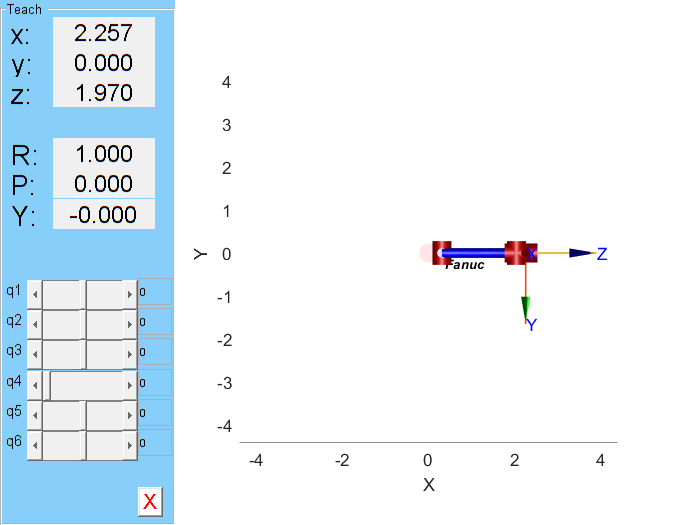

Robot.teach();

3.  Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el Toolbox explique:

- ¿Cuál es la diferencia entre estas funciones?

- ¿Cuál debe usar para su robot y por qué? (Revise la documentación del Toolbox)

%q = Robot.ikine6s(T_0_6)

4. Haga uso del RST para hallar la cinemática inversa de su robot asignado y compruebe los resultados anteriores.

body1 = rigidBody('body1');
body2 = rigidBody('body2');
body3 = rigidBody('body3');
body4 = rigidBody('body4');
body5 = rigidBody('body5');
body6 = rigidBody('body6');

jnt1 = rigidBodyJoint('jnt1','revolute');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt6 = rigidBodyJoint('jnt6','revolute');

% jnt1.HomePosition = 0;
% jnt2.HomePosition = 0;
% jnt3.HomePosition = 0;
% jnt4.HomePosition = 0;
% jnt5.HomePosition = 0;
% jnt6.HomePosition = 0;

tform1 = A_0_1;
tform2 = A_1_2;
tform3 = A_2_3;
tform4 = A_3_4;
tform5 = A_4_5;
tform6 = A_5_6;

mdhparams = [0     0     0.67  0;
             0.312 -pi/2 0     -pi/2;
             1.075 0     0     0;
             0.225 -pi/2 1.73  0;
             0     pi/2  0     0;
             0     -pi/2 0.215 0];

setFixedTransform(jnt1,mdhparams(1,:),'mdh');
setFixedTransform(jnt2,mdhparams(2,:),'mdh');
setFixedTransform(jnt3,mdhparams(3,:),'mdh');
setFixedTransform(jnt4,mdhparams(4,:),'mdh');
setFixedTransform(jnt5,mdhparams(5,:),'mdh');
setFixedTransform(jnt6,mdhparams(6,:),'mdh');

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;

robot = rigidBodyTree;

addBody(robot,body1,'base');
addBody(robot,body2,'body1');
addBody(robot,body3,'body2');
addBody(robot,body4,'body3');
addBody(robot,body5,'body4');
addBody(robot,body6,'body5');

bodyEndEffector = rigidBody('endeffector');

setFixedTransform(bodyEndEffector.Joint,trvec2tform([0, 0, 0]));

addBody(robot,bodyEndEffector,'body6');

config = randomConfiguration(robot)

config = 1×6 struct array with fields:
    JointName
    JointPosition


tform = getTransform(robot,config,'endeffector','base')

tform =    -0.3050   -0.3159    0.8984   -2.0273
   -0.1837    0.9452    0.2700   -1.7708
   -0.9345   -0.0827   -0.3463   -0.5755
         0         0         0    1.0000




gik = generalizedInverseKinematics;
gik.RigidBodyTree = robot;
gik.ConstraintInputs = {'position','aiming'};
posTgt = constraintPositionTarget('endeffector');
posTgt.TargetPosition = [2.257 0 1.97];
aimCon = constraintAiming('endeffector');
aimCon.TargetPoint = [1 0 0];
q0 = homeConfiguration(robot); % Initial guess for solver
[q,solutionInfo] = gik(q0,posTgt,aimCon)

q = 1×6 struct array with fields:
    JointName
    JointPosition


solutionInfo = struct with fields:
              Iterations: 59
       NumRandomRestarts: 0
    ConstraintViolations: [1×2 struct]
                ExitFlag: 7
                  Status: 'success'


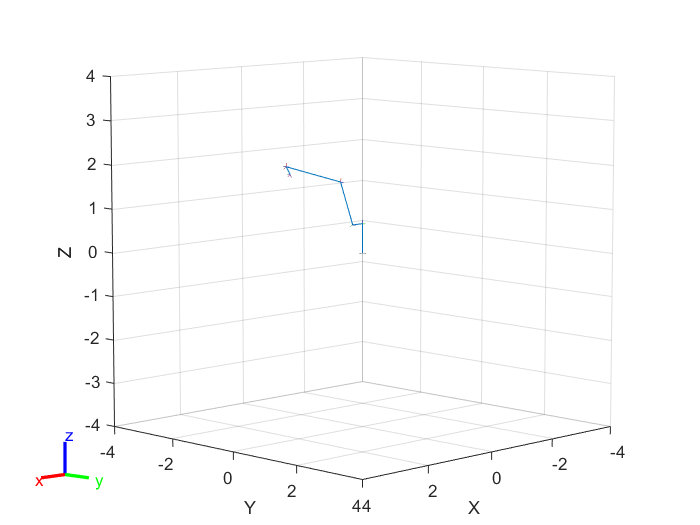

show(robot,q);